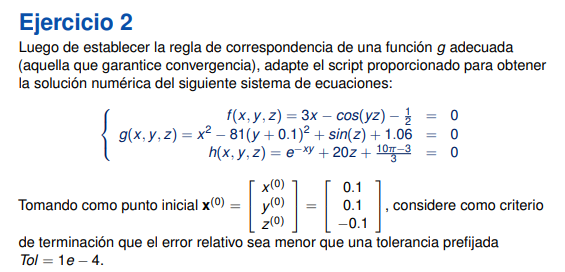

Se tiene el siguiente sistema: 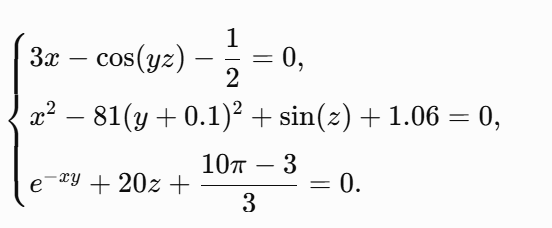

## Despejamos x, y , z

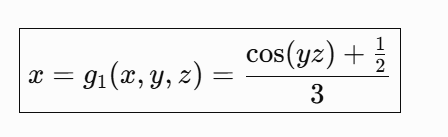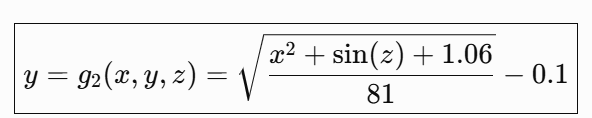

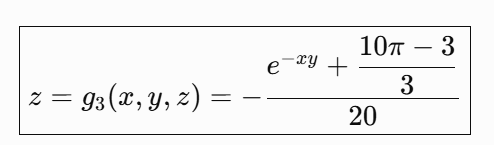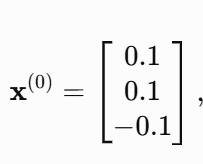

clear; clc;                                                   % Limpia las variables y la ventana de comandos

G = @(x) [(cos(x(2)*x(3)) + 1/2)/3; ...                      % Define x = g1(x,y,z)
    sqrt((x(1)^2 + sin(x(3)) + 1.06)/81) - 0.1; ...    % Define y = g2(x,y,z)
    -(exp(-x(1)*x(2)) + (10*pi-3)/3)/20];              % Define z = g3(x,y,z)

x0 = [0.1; 0.1; -0.1];                                       % Define el punto inicial

Tol = 1e-4;                                                   % Define la tolerancia

dr = 1;                                                       % Inicializa el error relativo

i = 0;                                                        % Inicializa el contador de iteraciones

Z = [i x0' dr];                                               % Guarda iteración, x, y, z y error

while dr > Tol                                                % Repite mientras el error sea mayor que la tolerancia

    x1 = G(x0);                                               % Calcula la nueva aproximación por punto fijo

    dr = norm(x1-x0,'inf')/norm(x1,'inf');                    % Calcula el error relativo con norma infinito

    x0 = x1;                                                  % Actualiza el vector para la siguiente iteración

    i = i + 1;                                                % Incrementa el contador

    Z = [Z; i x1' dr];                                        % Guarda los resultados de la iteración

end                                                           % Finaliza el ciclo while

fprintf(' i          x             y             z              error\n') % Encabezado

 i          x             y             z              error



for j = 1:size(Z,1)                                           % Recorre todas las iteraciones

    fprintf('%2.0f    %10.6f    %10.6f    %10.6f    %12.6e\n', ... % Define el formato de salida
        Z(j,1),Z(j,2),Z(j,3),Z(j,4),Z(j,5))                  % Muestra cada iteración

end                                                           % Finaliza el ciclo de impresión

 0      0.100000      0.100000     -0.100000    1.000000e+00
 1      0.499983      0.009441     -0.523101    8.088324e-01
 2      0.499996      0.000026     -0.523363    1.799053e-02
 3      0.500000      0.000012     -0.523598    4.484842e-04
 4      0.500000      0.000000     -0.523598    2.349616e-05
